# Charcoal: Reconstruct Raman Spectra

## December 2024. 

Reconstruct spectra from Chris Marjo's deconvolutions for PLS

clear all
warning('off','all');
rlimit = 0.97;  %do not use data with r^2<0.97
traw=readtable("ChrisPeakFits.xlsx","Sheet","Matlab")
t = traw(traw.R_sqrd>rlimit,:);
Wn = [900:2:2000]; % wavelengths for calculating pdf
Heat = t.Intensity;
file = string(t{:,1});

## Make pdfs

PD=Makepdf(t, Wn);
save('PD',"PD");

## preprocess #1

Normalise each spectrum to max of 1

load("PD.mat");
PDnorm1 = PD'./max(PD');

## Set up for PLS

ncomp = 10; %max number of components (Matlab)
Xraw = PDnorm1';
Y=Heat;
pre='mscmean' ; % for ipls none, mean, auto, mscmean, mscauto (multiplicate signal correction) (IToolbox)
cv = 'syst123'; %cross validation method (iToolbox)
windows= 10; %intervals for ipls and bipls (iToolBox)


## Matlab PLS

display('MATLAB')
[Xcor,Xcormeancal]=msc(Xraw); % multiplicative scatter correction
[X,mx]=mncn(Xcor); % mean centre

[n,p] = size(X);
[Xl,Yl,Xs,Ys,beta,pctVar,PLSmsep] = plsregress(X,Y,ncomp,'CV',5);
figure; plot(0:ncomp,PLSmsep(2,:),'b-o');
xlabel('Number of components');
ylabel('Estimated Mean Squared Prediction Error');
% now run pls with optimum ncomp
[A,nOpt]=min(PLSmsep,[],2); nopt=nOpt(2)-1;
[Xloadings,Yloadings,Xscores,Yscores,betaPLS] = plsregress(X,Y,nopt);
yfitPLS = [ones(n,1) X]*betaPLS;
mdl = fitlm(Y,yfitPLS);
rmse(yfitPLS,Y)
mdl.Rsquared.Ordinary
figure; plot(Y,yfitPLS,'bo', Y, Y, '-');
xlabel('Observed Response');
ylabel('Fitted Response');


## IPLS model

display('IPLS')

IPLS


X = Xraw;
Model=ipls(X,Y,10,pre,windows,Wn,cv,5);
plsrmse(Model,0);

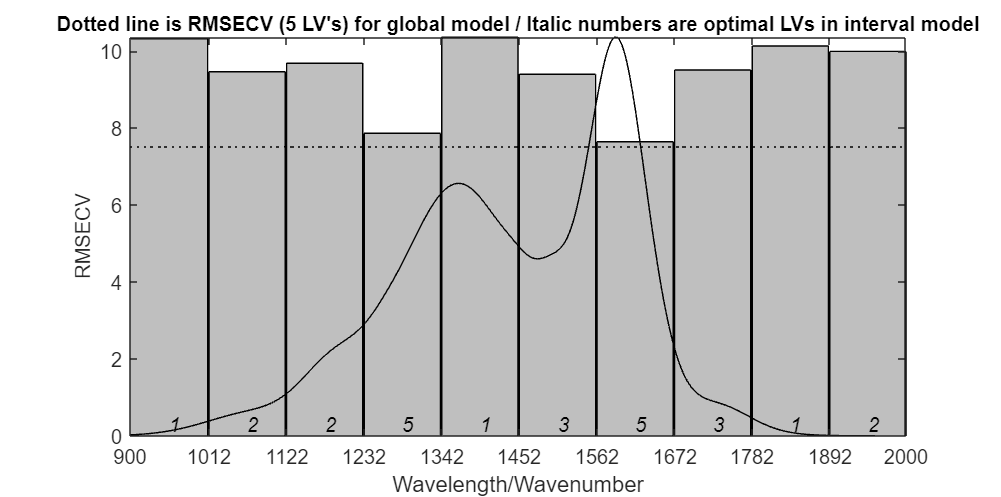

iplsplot(Model,'wavlabel',5)

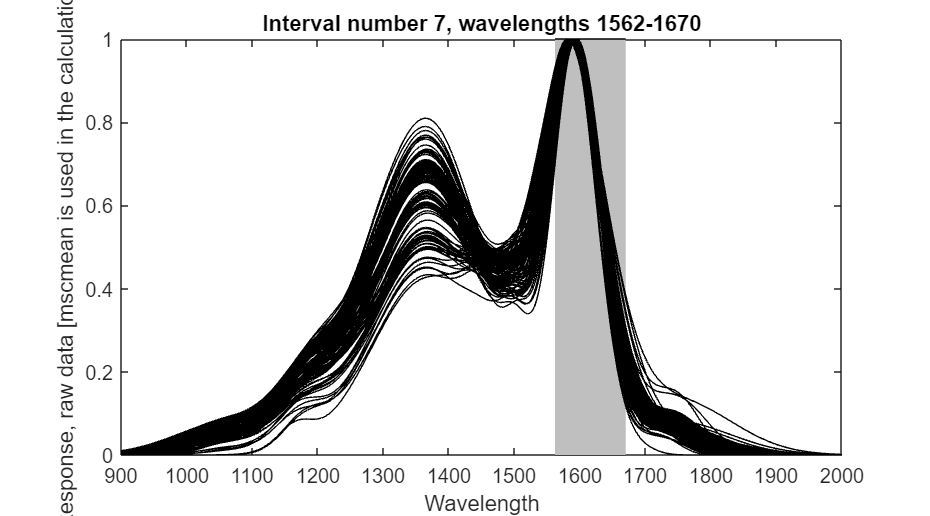

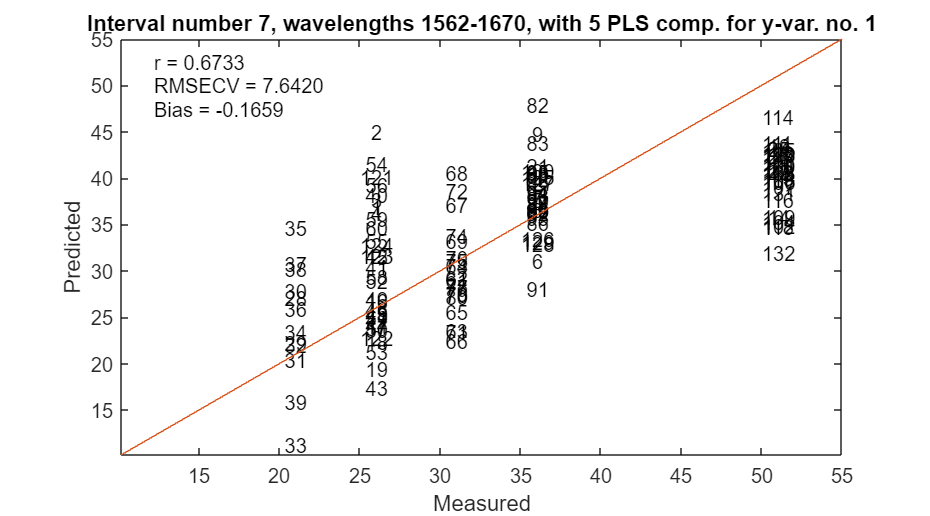

plspvsm(Model,5,7)  %best 

## BiPLS model for all species

display('BIPLS')

BIPLS


X = Xraw;
biModel=bipls(X,Y, 10,pre,windows,Wn,cv,5);
biplstable(biModel)

 
    Number    Interval    RMSE      Number of Variables
    ---------------------------------------------------
      10          3       7.3912           551
       9          2       7.2747           496
       8          1       7.1001           441
       7          9       6.9707           385
       6         10       6.9632           330
       5          8       7.0135           275
       4          6       6.8936           220
       3          5       6.8113           165
       2          4       7.0475           110
       1          7       7.6420            55
 


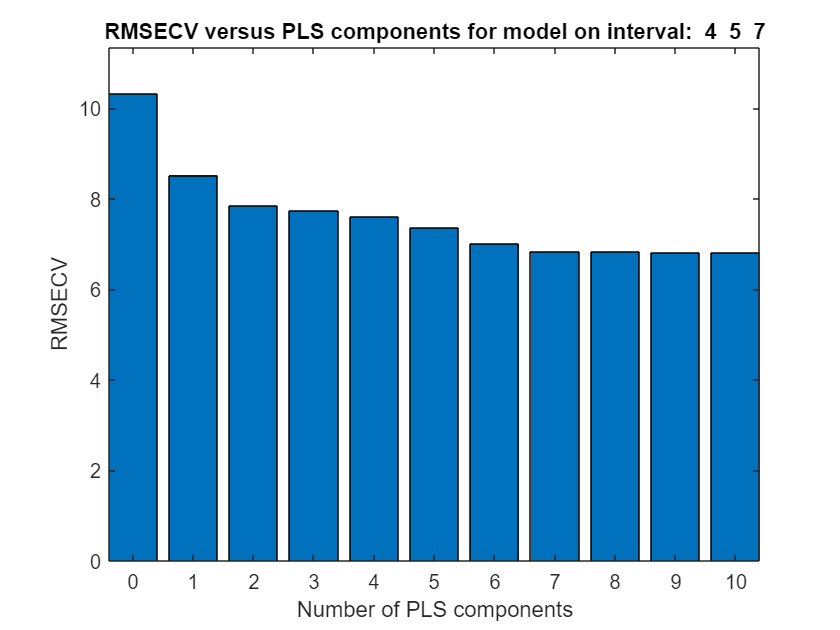

FinalModel=plsmodel(biModel,[4 5 7],10,pre,cv,5); 
plsrmse(FinalModel); 

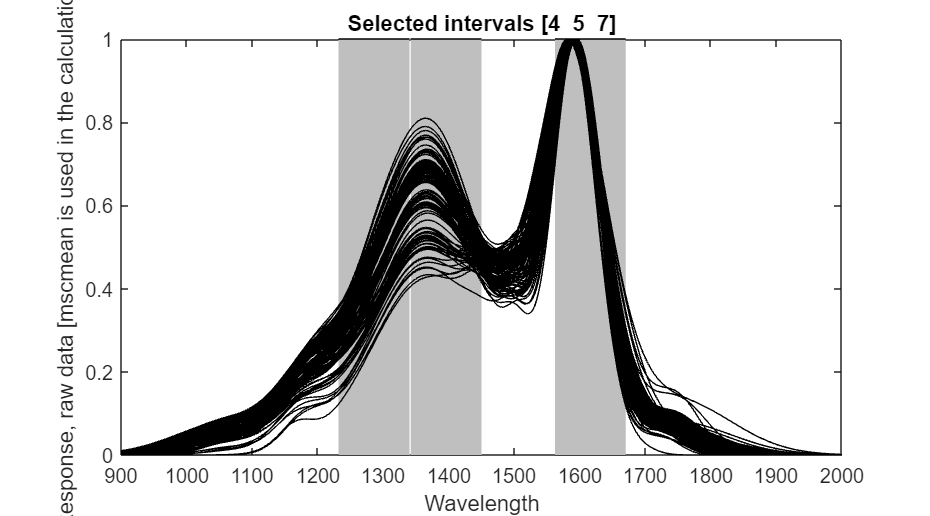

plspvsm(FinalModel,9);

yfitbiPLS = FinalModel.PLSmodel{1}.Ypred(:,1,9);
mfun = @(b,x)b(1)*b(2)*x./(1+b(2)*x);
beta0 = [92 0.02];
lmdl = fitnlm(Y,yfitbiPLS,mfun,beta0)

lmdl = Nonlinear regression model:
    y ~ b1*b2*x/(1 + b2*x)

Estimated Coefficients:
          Estimate       SE        tStat       pValue  
          ________    _________    ______    __________

    b1      93.155       11.623    8.0146    5.3388e-13
    b2    0.017403    0.0035417    4.9137    2.6195e-06


Number of observations: 133, Error degrees of freedom: 131
Root Mean Squared Error: 5.53
R-Squared: 0.578,  Adjusted R-Squared 0.575
F-statistic vs. zero model: 2.61e+03, p-value = 3e-106

sqrt(lmdl.Rsquared.Ordinary)

ans = 0.7604

ynew = predict(lmdl,[15:55]');
hold on;
plot([15:55]',ynew,'r-',LineWidth=2); hold off;

## BIPLS model for Silvertop Ash

use nomalised spectra

display('BIPLS Silvertop Ash')

BIPLS Silvertop Ash


XrawS = Xraw(find(contains(file,'Silver')),:);
YS = t.Intensity(find(contains(file,'Silver')));
biSModel=bipls(XrawS,YS, 12,pre,windows,Wn,cv,5);
biplstable(biSModel)

 
    Number    Interval    RMSE      Number of Variables
    ---------------------------------------------------
      10          1       6.5231           551
       9         10       6.4839           495
       8          9       6.4577           440
       7          2       6.4411           385
       6          8       6.4199           330
       5          6       5.7097           275
       4          3       5.4016           220
       3          5       5.3870           165
       2          7       5.3436           110
       1          4       6.7282            55
 


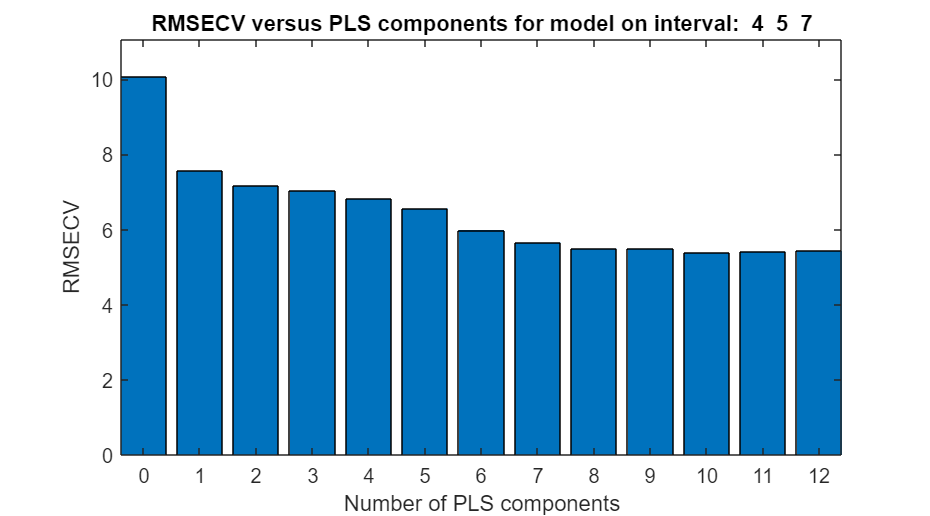

FinalSModel=plsmodel(biSModel,[4 5 7],12,pre,cv,5); 
plsrmse(FinalSModel); 

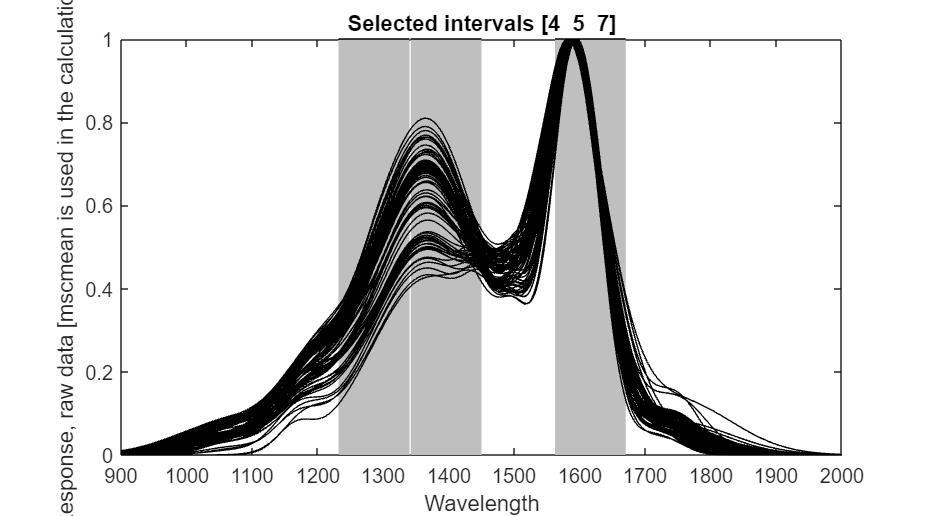

plspvsm(FinalSModel,10); 

yfitbiSPLS = FinalSModel.PLSmodel{1}.Ypred(:,1,7);
mfun = @(b,x)b(1)*b(2)*x./(1+b(2)*x);
beta0 = [92 0.02];
lSmdl = fitnlm(YS,yfitbiSPLS,mfun,beta0)

lSmdl = Nonlinear regression model:
    y ~ b1*b2*x/(1 + b2*x)

Estimated Coefficients:
          Estimate       SE        tStat       pValue  
          ________    _________    ______    __________

    b1     132.63        26.144    5.0731    2.0549e-06
    b2    0.01023     0.0027644    3.7006    0.00036803


Number of observations: 93, Error degrees of freedom: 91
Root Mean Squared Error: 4.99
R-Squared: 0.689,  Adjusted R-Squared 0.685
F-statistic vs. zero model: 2.12e+03, p-value = 4.87e-77

sqrt(lSmdl.Rsquared.Ordinary)

ans = 0.8300

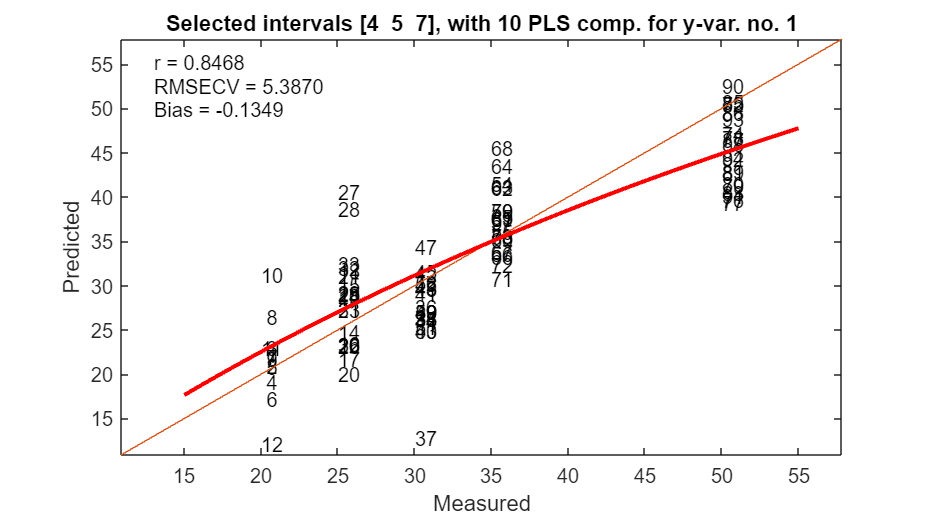

ynewS = predict(lSmdl,[15:55]');
hold on;
plot([15:55]',ynewS,'r-',LineWidth=2); hold off;

# Swamp data

From data in ...\Maame and Brynn Raman data play space\Raman Spectra data & PLS model (swamp charcoal) _Maame\MarjoRefit

Rocky Point not included (only D and G fits)

tSraw=readtable("ChrisSwampPeakFits.xlsx","Sheet","Matlab")

tSraw = 347×50 table
                                                   File                                                         Swamp          Depth_m         StdErr          R_sqrd     DPos     DHt     DFwhm      DArea       D_area    G_GPos    G_GHt    G_GFwhm     G_GArea      G_G_area    S_LPos    S_LHt    S_LFwhm     S_LArea      S_L_area    SPos    SHt     SFwhm    SArea    S_area    D_SPos    D_SHt    D_SFwhm    D_SArea    D_S_area    A_1Pos    A_1Ht

Swamps =unique(string(tSraw.Swamp));
tSwamp = tSraw(tSraw.R_sqrd>rlimit,:);

## Make Gaussian pdfs

PDS = Makepdf(tSwamp,Wn);
save('PDS',"PDS");

## Obtain Intensities from PLS calibration using normalised spectra

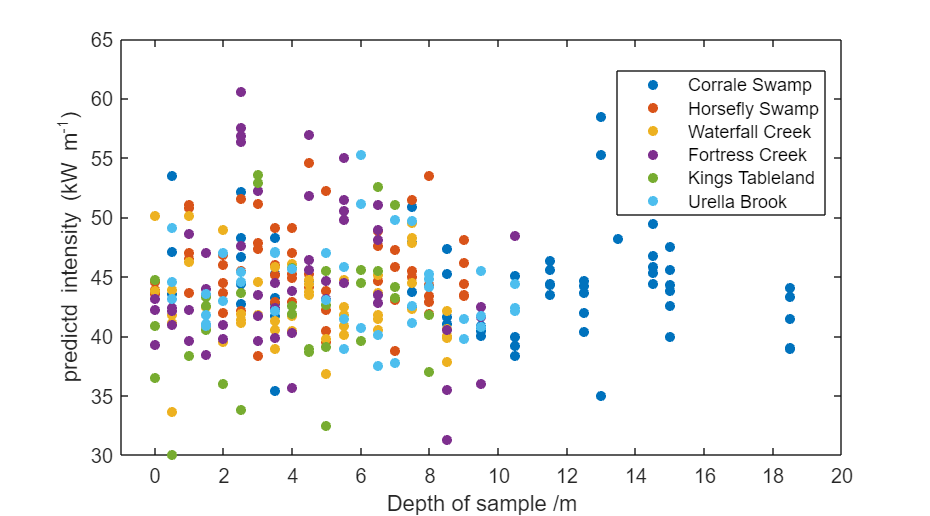

PDSnorm1 = PDS'./max(PDS');
ySwpred = plspredict(PDSnorm1',FinalModel,7);
a = lmdl.Coefficients{1,1}; b=lmdl.Coefficients{2,1};
ESwamp = a*(b.*ySwpred.Ypred(:,1,7)./(1+b.*ySwpred.Ypred(:,1,7))); %back calculate intensity
gscatter(tSwamp.Depth_m,ESwamp,tSwamp.Swamp)
xlabel('Depth of sample /m'); ylabel('predictd intensity (kW m^{-1})')

## subroutines

function [Xmsc,Xmeancal]=msc(X)
[n,m]=size(X);
Xmeancal=mean(X);
for i=1:n
  coef=polyfit(Xmeancal,X(i,:),1);
  Xmsc(i,:)=(X(i,:)-coef(2))/coef(1);
end
end

function [Xmean,meanX] = mncn(X)
[n,m] = size(X);
meanX = mean(X);
Xmean = (X-meanX(ones(n,1),:));
end

function PD = Makepdf(t,Wn) % Takes peak data in table 't' and calculates Gaussian pdf at wavelengths Wn
fwhm =1/(2*sqrt(2* log(2))); % x to give sigma from fwhm

for i=1:size(t,1)
    Pos(i,1) = t.DPos(i); Pos(i,2)=t.G_GPos(i); Pos(i,3)=t.S_LPos(i);Pos(i,4)=t.SPos(i);
    Pos(i,5)=t.D_SPos(i); Pos(i,6)=t.A_1Pos(i);Pos(i,7)=t.A_2Pos(i);Pos(i,8)=t.G_LPos(i); Pos(i,9)=t.CPos(i);
    Fwhm(i,1) = t.DFwhm(i); Fwhm(i,2)=t.G_GFwhm(i); Fwhm(i,3)=t.S_LFwhm(i);Fwhm(i,4)=t.SFwhm(i);
    Fwhm(i,5)=t.D_SFwhm(i); Fwhm(i,6)=t.A_1Fwhm(i);Fwhm(i,7)=t.A_2Fwhm(i);Fwhm(i,8)=t.G_LFwhm(i); Fwhm(i,9)=t.CFwhm(i);
    Area(i,1) = t.DArea(i); Area(i,2)=t.G_GArea(i); Area(i,3)=t.S_LArea(i);Area(i,4)=t.SArea(i);
    Area(i,5)=t.D_SArea(i); Area(i,6)=t.A_1Area(i);Area(i,7)=t.A_2Area(i);Area(i,8)=t.G_LArea(i); Area(i,9)=t.CArea(i);
end
% construct pdf parameters
for i=1:size(t,1)
    for j=1:9
        D(i,j)=makedist("Normal","mu",Pos(i,j),"sigma",Fwhm(i,j)*fwhm);
    end
end
% construct pdf

for i=1:size(t,1) %for each spectrum
    thisPD=0;
        for j=1:9 %for each component
           thisPD = thisPD+Area(i,j)*pdf(D(i,j),Wn);
        end
     PD(i,:)=thisPD;
end
end
